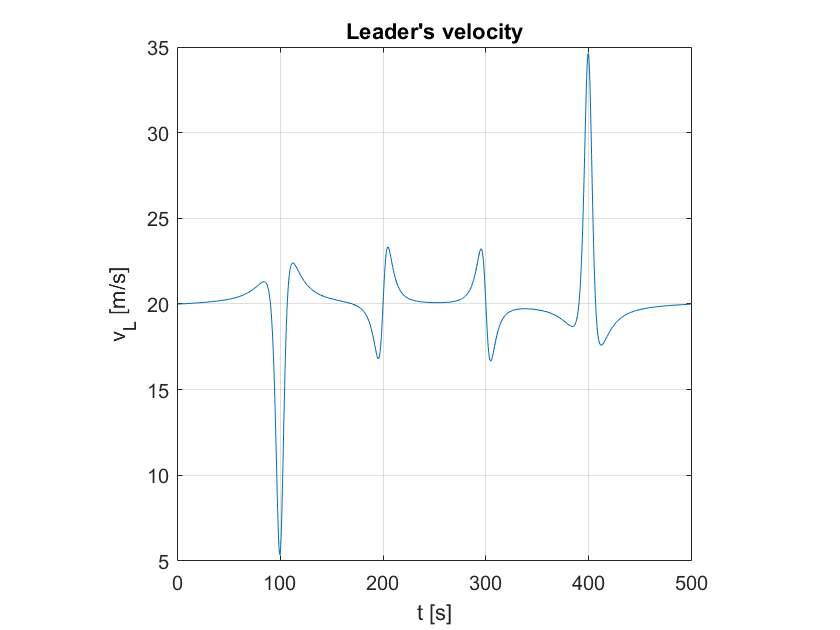

%HW8 Question 1
% Plotting energy contours on top of string stable domain 
% Create stability charts with energy optimum for CCC with 4 vehicles
clear; clc;
% close all;

%% Parameters

    kappa_0 = 0.6;
    sigma_0 = 0.6;
    kappa_h = 0.69;
    tau = 0.8;
    alpha_h = 0.2;
    beta_h = 0.6;

    alpha_01 = 0.4;
    beta_02 = 0.0;
    
    beta_01min=-0.5;    
    beta_01max=1;     
    beta_03min=-0.5;	
    beta_03max=1;     
    step=200;

zeta = 0.4;
gamma_01 = 0.5;
gamma_03 = 0;

% specify leader's velocity
vstar = 29;
t0=0; tend=500;
vamp = 5;

om = 2*pi/500;
vstar = 20;

%vL= @(t)vstar + vamp*cos(om*t);
syms i
vL= @(t)vstar+double(symsum(25*i*om*exp(-8*om*i)*sin(om*i/0.01)*cos(om*i*t + 2*pi*cos(om*i/0.01)),i,1,100));  


%vL=@(t)vstar+3*sin(0.1*2*pi*t)+1*sin(0.3*2*pi*t);
% vL=@(t)vstar-3*sawtooth(-0.1*2*pi*t)-3;       
% vL=@(t)vstar+3*square(0.1*2*pi*t);
% t1=10; t2=30;
% vL0=vstar; vL1=vstar-10; vL2=vstar; vLend=vstar; 
% vL=@(t)(t<t0).*vL0+...
%        (t0<=t & t<t1).*(vL0+(vL1-vL0)/(t1-t0)*(t-t0))+...
%        (t1<=t & t<t2).*(vL1+(vL2-vL1)/(t2-t1)*(t-t1))+...
%        (t2<=t & t<=tend).*(vL2+(vLend-vL2)/(tend-t2)*(t-t2));


%% FFT of leader's velocity
% calculate leader's velocity values along time interval
deltat=0.5;
n=2^nextpow2((tend-t0)/deltat);
deltat=(tend-t0)/(n-1);
time=t0:deltat:tend;
vLead=vL(time);

% plot leader's velocity
figure(1); clf;
hold on; box on; grid on;
plot(time,vLead);
pbaspect([1 1 1]);
xlabel('t [s]');
ylabel('v_L [m/s]');
title('Leader''s velocity');

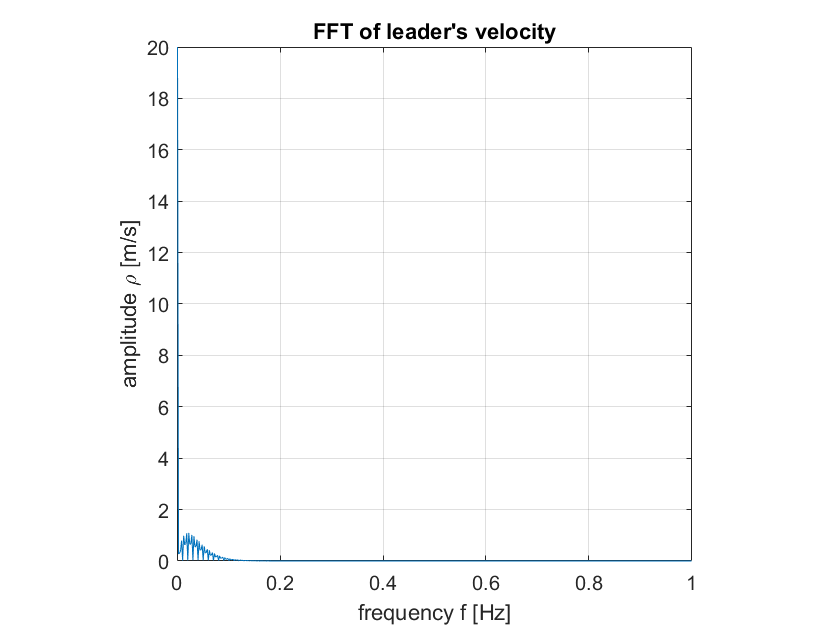

%saveas(gcf,"Output_Graphs\Output_Graphs\CCC_4_Vehicles_EnergyOptimization\Leaders_velocity.jpg");

% calculate frequency content of leader's velocity

fs=1/deltat;                % sampling frequency
VL=fft(vLead,n);            % FFT of leader's velocity
rho_v=abs(VL(1:n/2+1)/n);	% corresponding amplitudes
rho_v(2:end-1)=2*rho_v(2:end-1);
freq_v=fs*(0:(n/2))/n;      % corresponding frequencies
om_v=2*pi*freq_v;           % corresponding angular frequencies
ommin=min(om_v);
ommax=max(om_v);

% plot FFT of leader's velocity
figure(2);
hold on; box on; grid on;
plot(freq_v,rho_v);
xlim([0,1]);
pbaspect([1 1 1]);
xlabel('frequency f [Hz]');
ylabel('amplitude \rho [m/s]');
title('FFT of leader''s velocity');

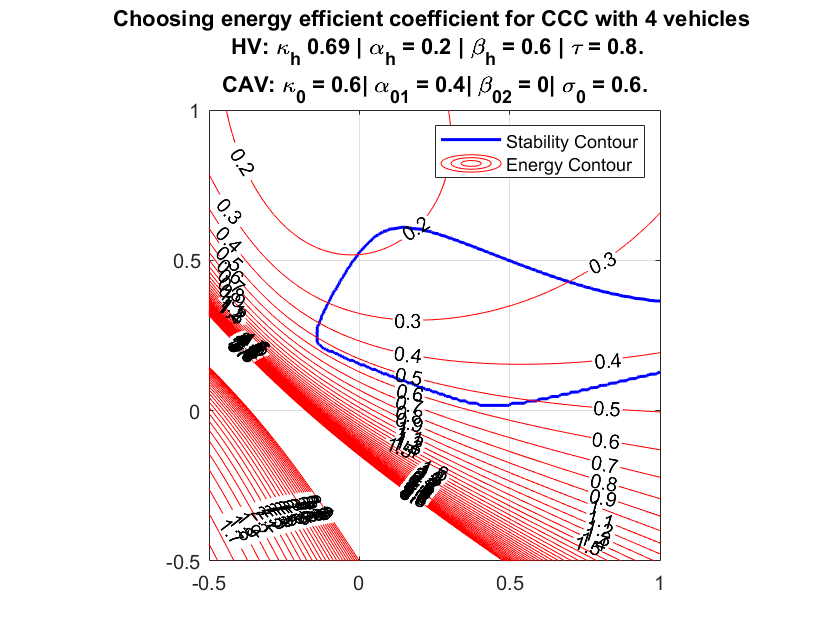

%saveas(gcf,"Output_Graphs\Output_Graphs\CCC_4_Vehicles_EnergyOptimization\Leaders_velocity_FFT.jpg");


beta_03_v=linspace(beta_03min,beta_03max,step+1);
beta_01_v=linspace(beta_01min,beta_01max,step+1);
    
% matrix of parameter, frequency and transfer function values
[beta_01,beta_03,om] = meshgrid(beta_01_v,beta_03_v,om_v);

% Head to tail transfer function for 3 vehicle ahead of CAV.(from hw7 ques 1) (Total 4)
G03 = (beta_03.*om.*1i)./...
       (alpha_01.*kappa_0 + alpha_01.*om.*1i + beta_01.*om.*1i + beta_02.*om.*1i + beta_03.*om.*1i - om.^2.*exp(om.*sigma_0.*1i)) +...
       (exp(-om.*tau.*2i).*(alpha_01.*kappa_0 + beta_01.*om.*1i).*(alpha_h.*kappa_h + beta_h.*om.*1i).^2)./...
       ((exp(-om.*tau.*1i).*(alpha_h.*kappa_h + om.*(alpha_h + beta_h).*1i) - om.^2).^2.*(alpha_01.*kappa_0 + alpha_01.*om.*1i + beta_01.*om.*1i + beta_02.*om.*1i + beta_03.*om.*1i - om.^2.*exp(om.*sigma_0.*1i))) +...
       (beta_02.*om.*exp(-om.*tau.*1i).*(alpha_h.*kappa_h + beta_h.*om.*1i).*1i)./...
       ((exp(-om.*tau.*1i).*(alpha_h.*kappa_h + om.*(alpha_h + beta_h).*1i) - om.^2).*(alpha_01.*kappa_0 + alpha_01.*om.*1i + beta_01.*om.*1i + beta_02.*om.*1i + beta_03.*om.*1i - om.^2.*exp(om.*sigma_0.*1i)));


% matrix of maximum head-to-tail transfer function magnitudes
Mmax=max(abs(G03(:,:,0<om_v)),[],3);

%% Evaluation of energy consumption
% matrix of amplitudes
[~,~,rho]=meshgrid(beta_01_v,beta_03_v,rho_v);
% response amplitudes
D=abs(G03).*rho;
% matrix of cost function values
J=sum(D.^2.*om.^2,3);

%% Plot stability chart and energy consumption
figure(3); hold on; box on; grid on;
% string stability
contour(beta_01(:,:,1),beta_03(:,:,1),Mmax,[1,1],'b','Linewidth',1.5);
% energy consumption
contour(beta_01(:,:,1),beta_03(:,:,1),J,0:0.1:4,'r','ShowText','on');
axis([beta_01min beta_01max beta_03min beta_03max]);
pbaspect([1 1 1]);
xlabel('\beta_{01} [1/s]')
ylabel('\beta_{03} [1/s]')
title({"Choosing energy efficient coefficient for CCC with 4 vehicles ",...
    " HV: \kappa_h "+kappa_h+" | \alpha_h = "+alpha_h+" | \beta_h = "+beta_h+" | \tau = "+tau+".","CAV: \kappa_0 = "+0.6+"| \alpha_{01} = "+alpha_01+"| \beta_{02} = "+beta_02+"| \sigma_0 = "+sigma_0+"."});
legend('Stability Contour','Energy Contour');

%saveas(gcf,"Output_Graphs\Output_Graphs\CCC_4_Vehicles_EnergyOptimization\Energy_contour.jpg");
